# Taller 2

### 26/06/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 2 y 3*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

### Sobre Punto fijo

*Para explorar este método, es importante primero revisar lo que es un punto fijo. Un ****punto fijo ***$\beta$* de una función *$f$* es un punto cuya imagen producida *$f\left(\beta \right)$* es él mismo. Es decir, *$\beta$* es un punto fijo de la función *$f$* si y sólo si *$f\left(\beta \right)=\beta$*.*

Con esta claridad, veamos que podemos reducir un punto fijo a las soluciones de la igualdad $f\left(x\right)=x$. Estos puntos fijos podemos considerarlo como atractivos, si a partir de un punto $x_0$ la sucesión ${\left\lbrace {x^* }_n \right\rbrace }_{n\;=\;n_0 }^{\infty }$ tras infinitas iteraciones converge al punto fijo $\beta$, o sea lo vemos en la practica como:

$\left\lbrace x_0 ,f\left(x_0 \right),\ldotp \ldotp \ldotp \;,f\left(f\left(\ldotp \ldotp \ldotp f\left(x_0 \right)\right)\right)\right\rbrace$       o       $f\left(f\left(\ldotp \ldotp \ldotp f\left(x_0 \right)\right)\right)\underset{n\;\to \infty }{\to} \;x$

Veamos este hecho tomando de ejemplo una de las funciones $f$, interactuando se restringirá un intervalo $I$, donde podemos asegurar la existencia de un único *punto fijo atractivo*:

clear
syms x y real
clf('reset')

FunStrings = ["cos(x)-cos(3.1*x)", "1/2 .*( sin(x) + cos(x) )", "6.^-x", "5 ./ x.^3 + 2"];
FunInterval = {[-1, 1.75], [0, 1], [0, 1], [2, 4]};
x0Reseting = [1.5, 1/4, .25, 3.75];
Function = "6.^-x";

f = str2func("@(x) " + Function);

I = FunInterval(Function == FunStrings);
I = cell2mat(I);

Función seleccionada:

disp(f(x))

$$\frac{1}{6^{x}}$$

Intervalo a revisar:

disp("(a, b) = ("+ num2str(I(1)) + ", " + num2str(I(2)) + ")")

(a, b) = (0, 1)


Partamos de la idea propuesta anteriormente, ya definido el intervalo, procedemos a hallar el valor de la función en la estimación inicial e iteramos de ahí, modifiquemos el valor inicial:

m_expr = @(x) f(x);
a = I(1);
b = I(2);
x0 = 1;

if (x0 < a) || (x0 > b)
    x0 = x0Reseting(Function == FunStrings);
end
disp("Estimación inicial:  " + num2str(x0))

Estimación inicial:  0.25


disp('h')

h


disp(sym(m_expr));

$$\frac{1}{6^{x}}$$

A continuación selecciónar el número de pasos a mostrar del algoritmo a continuación:

N = 3;
% For loop de Cálculo:
c = x0;

for k = 1:N
    disp("Veamos que en la iteración " + num2str(k) + " sucede que:")
    
    disp("Tomando el valor x = " + num2str(c))
    
    c = f(c);
    disp("El valor que hallamos es h = " + num2str(c))
   
    disp("Así nuestro nuevo valor de estimación inicial x es: " + num2str(c))
    disp(' ')
    
    c = f(c);
end

Veamos que en la iteración 1 sucede que:


Tomando el valor x = 0.25


El valor que hallamos es h = 0.63894


Así nuestro nuevo valor de estimación inicial x es: 0.63894


Veamos que en la iteración 2 sucede que:


Tomando el valor x = 0.31828


El valor que hallamos es h = 0.56537


Así nuestro nuevo valor de estimación inicial x es: 0.56537


Veamos que en la iteración 3 sucede que:


Tomando el valor x = 0.36313


El valor que hallamos es h = 0.52171


Así nuestro nuevo valor de estimación inicial x es: 0.52171


Estos son algunos de los pasos que se siguen para halla el resultado, veamos que esto gráficamente se expresa como: 

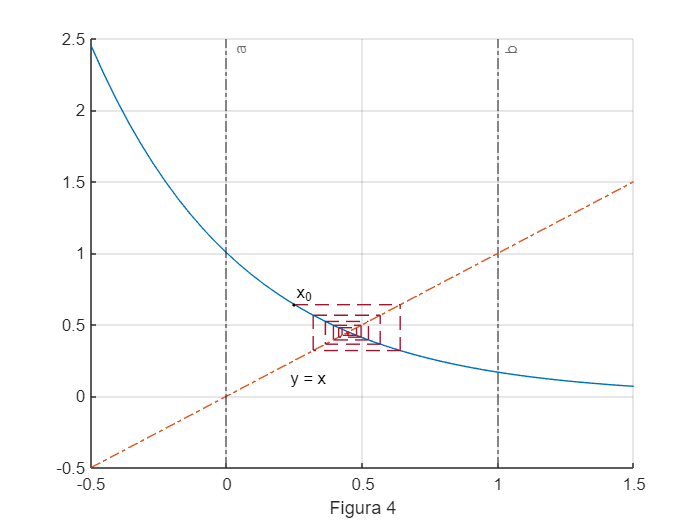

% For-Loop de gráficación
a = I(1) - 1/2;
b = I(2) + 1/2;

PF = vpasolve(f(x) == x, x, [a + 4/7, b - 1/2]);

clf('reset')
hold on
fplot(f, [a, b]);

fplot(x, [a, b], '-.')
text(PF - 1/4, PF - 1/4, '  y = x','VerticalAlignment','top','HorizontalAlignment','left')
plot(PF, PF, '.r')
plot(x0, f(x0), '.', 'Color', [0,0,0])
text(x0, f(x0), '  x_0','VerticalAlignment','bottom','HorizontalAlignment','center')

xline(I(1), '-.', 'a')
xline(I(2),'-.', 'b')

c = x0;
for k = 1:10
    
    yc = c;
    c = f(c);
    plot([yc, c], [f(yc), f(yc)], '--', 'Color', [0.6350, 0.0780, 0.1840])
    plot([c, c], [f(c), f(yc)], '--', 'Color', [0.6350, 0.0780, 0.1840])
end

grid on
xlabel('Figura 4')
hold off

### Bisección y Punto fijo

*Desarrollaremos el primer taller, para esta primera sección resolveremos *$\left.\left.\left.13\right),14\right)\;y\;16\right)$.

**13. **En cada una de las siguientes ecuaciones, determine un intervalo $\left\lbrack a,b\right\rbrack$ en el que converge la iteración de **punto fijo**. Estime la cantidad de iteraciones necesarias para obtener aproximaciones del punto fijo con una exactitud de `1e-5` . Utilice el punto medio del intervalo seleccionado como primera aproximación $p_0$:

**(a) **$\frac{\cos \left(x\right)+\sin \left(x\right)}{2}$        **(b)** $\frac{5}{x^2 }+2$        **(c) **$6^{-x}$

clear
syms f(x)
% Vamos a hacer el punto c)
f(x) = 6^(-x)

$$f(x) = \frac{1}{6^{x}}$$

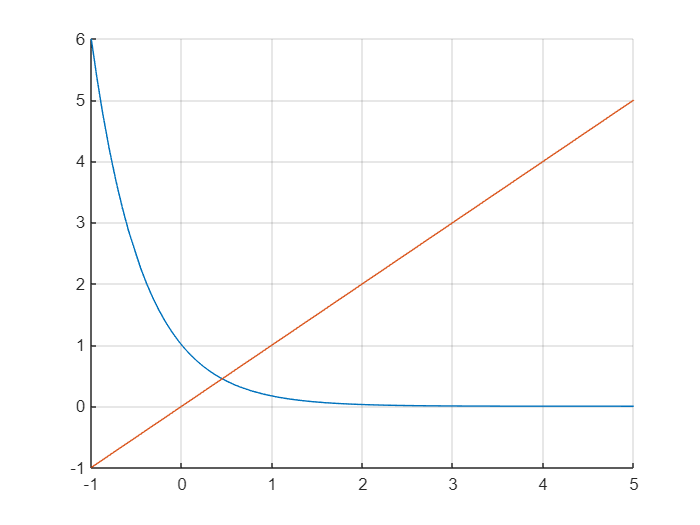

clf('reset')
hold on
fplot(f, [-1, 5])
fplot(@(x) x, [-1, 5])
grid on
hold off

% Criterio de la derivada : Unicidad
% |f'(x)| < 1 : Para unicidad y convergencia de PF
df(x) = abs(diff(f, x))

$$df(x) = \log\left(6\right)\,\left|\frac{1}{6^{x}}\right|$$

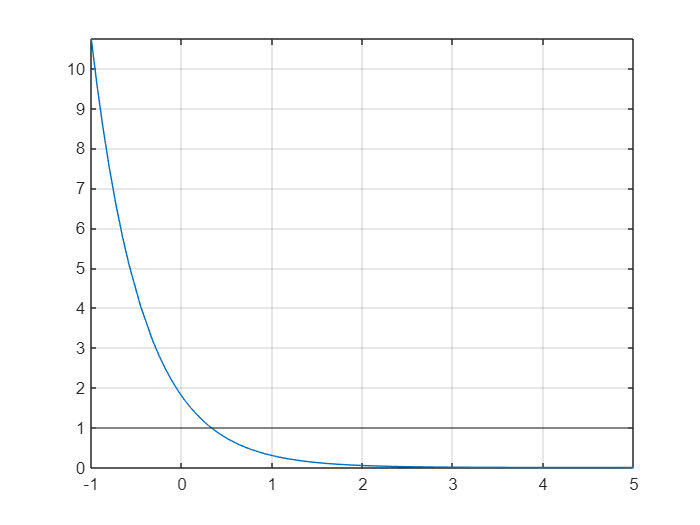

clf('reset')
fplot(df, [-1, 5])
yline(1)
grid on

% Primera forma de afrontar:
a = eval(solve(df(x)==1))

a = 0.3255

eval(df(a)), eval(df(a + 1)), eval(df(a - 1))

ans = 1.0000

ans = 0.1667

ans = 6.0000

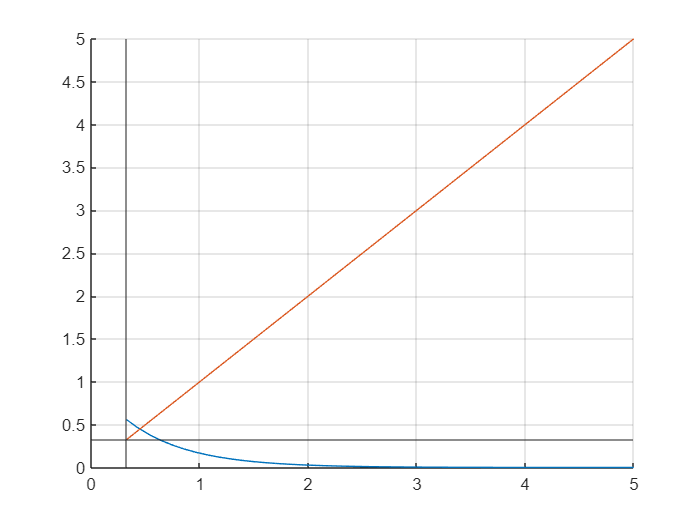

clf('reset')
hold on
fplot(f, [a, 5])
fplot(@(x) x, [a, 5])
yline(a)
xline(a)
grid on
hold off

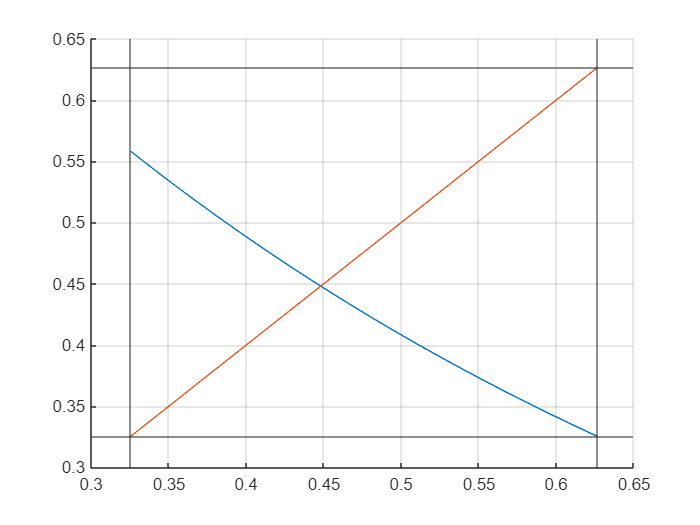

% Verificamos el valor b donde la función f(x) = a
b = eval(solve(f(x) == a));
% La gráfica acotada toma la forma:
clf('reset')
hold on
fplot(f, [a, b])
fplot(@(x) x, [a, b])
yline(a)
xline(a)
yline(b)
xline(b)
grid on
hold off

El intervalo de interes $\left\lbrack a,b\right\rbrack$ es:

I = [a, b]

I =     0.3255    0.6264


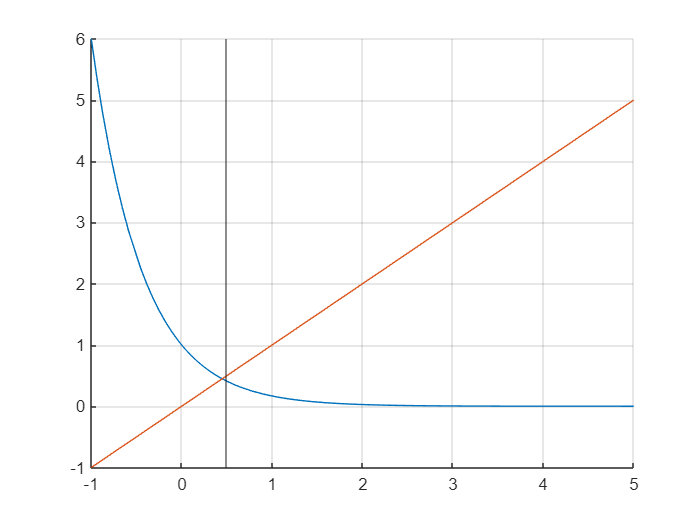

clf('reset')
hold on
fplot(f, [-1, 5])
fplot(@(x) x, [-1, 5])
xline(.5)
grid on
hold off

eval(df(.5))

ans = 0.7315

f = matlabFunction(f);
c = fixpt(f, .5, 1e-15, 1000)

c = 0.4481

**14. **Demuestre que las funciones siguientes tienen un punto fijo $p$ el cual cumple que $f\left(p\right)=0$, donde $f\left(x\right)=x^4 +2x^2 -x-3$:

**(a)** $g_1 \left(x\right)={\left(3+x-2x^2 \right)}^{\frac{1}{4}}$        **(b)** $g_2 \left(x\right)={\left(\frac{x+3}{x^2 +2}\right)}^{\frac{1}{2}}$        **(c) **$g_3 \left(x\right)=\;\frac{{3x}^4 +2x^2 +3}{4x^3 +4x-1}$

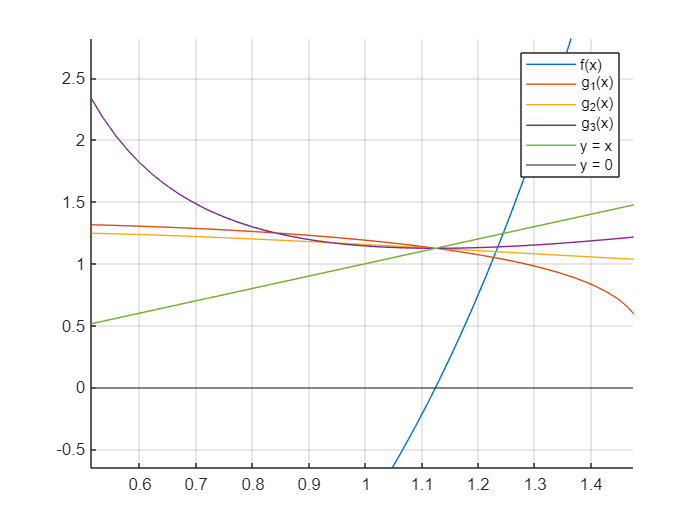

clear
syms g(x) [1, 2, 3]
syms f(x)

f(x) = x^4 + 2*x^2 - x - 3;

g_1(x) = (3 + x - 2*x^2)^(1/4);
g_2(x) = ((x + 3)/(x^2 + 2))^(1/2);
g_3(x) = (3*x^4 + 2*x^2 + 3)/(4*x^3 + 4*x - 1);

clf('reset')
hold on
fplot(f, [.5, 1.5])
fplot(g_1, [.5, 1.5])
fplot(g_2, [.5, 1.5])
fplot(g_3, [.5, 1.5])
fplot(@(x) x, [.5, 1.5])
yline(0)
legend('f(x)','g_1(x)', 'g_2(x)', 'g_3(x)', 'y = x', 'y = 0')
hold off
grid on

**16.** Use los dos métodos, bisección y punto fijo, para aproximar el punto de intersección de las curvas de las curvas $y=x^2 -2$ y $y=e^{-x}$

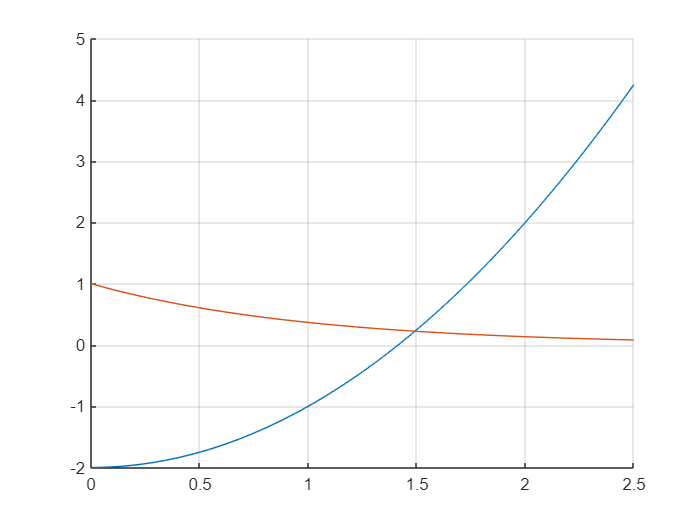

clear
syms f(x) g(x)

f(x) = x^2 - 2;
g(x) = exp(-x);

clf('reset')
hold on
fplot(f, [0, 2.5])
fplot(g, [0, 2.5])
grid on
hold off

$e^{-x} =x^2 -2$ Hipotesis a verificar

B(x) = f(x) - g(x)

$$B(x) = x^{2}-{\mathrm{e}}^{-x}-2$$

PF1(x) = sqrt(exp(-x) + 2)

$$PF1(x) = \sqrt{{\mathrm{e}}^{-x}+2}$$

PF2(x) = real(-log(x^2 - 2))

$$PF2(x) = -\log\left(\left|x^{2}-2\right|\right)$$

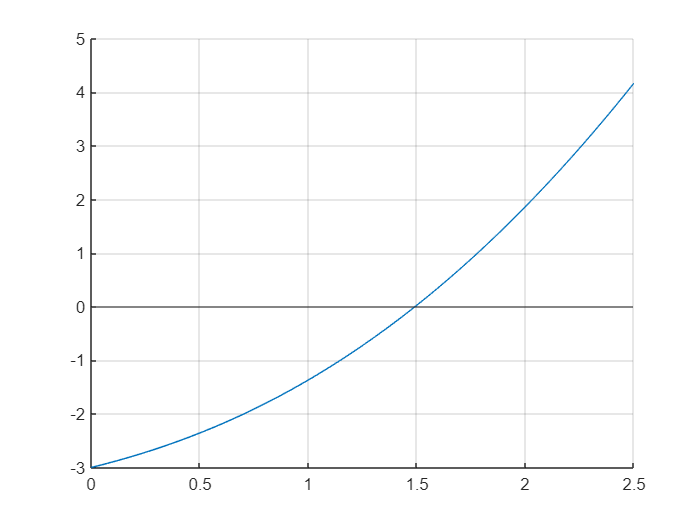

clf('reset')
hold on
fplot(B, [0, 2.5])
yline(0)
grid on
hold off

help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
          - maxIter Maximo de iteración
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



B = matlabFunction(B); % Convertir la función simbolica, en Matlab
[c, ~, errorBisect] = bisect(B, 0, 2.5, 1e-15)

c = 1.4916

errorBisect = -2.2204e-16

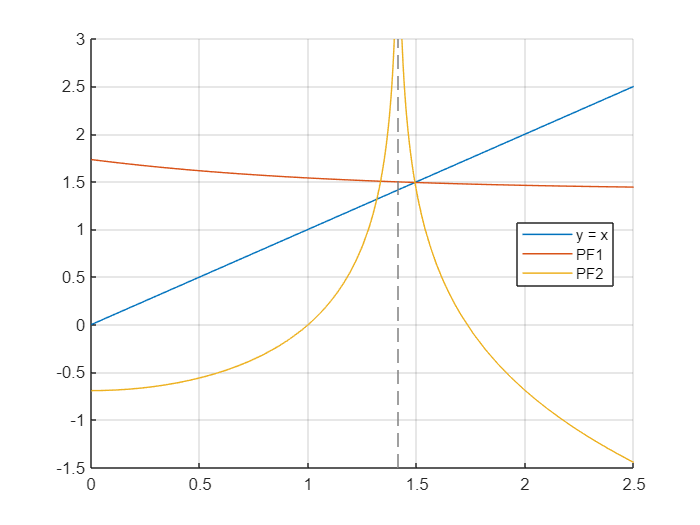

clf('reset')
hold on
fplot(@(x) x, [0, 2.5]) % Función y = x
fplot(PF1, [0, 2.5])
fplot(PF2, [0, 2.5])
legend('y = x', 'PF1', 'PF2', Location='best')
grid on
hold off

dPF1 = diff(PF1, x); dPF2 = diff(PF2, x);
% Verificación de la derivada en puntos cercanos al PF
eval(dPF1(1.5)), eval(dPF2(1.5))

ans = -0.0748

ans = -12

help fixpt

  Entrada - g funcion creada con @
          - p0 es el supuesto inicial para el punto fijo
          - tol es la tolerancia
          - max1 es el numero maximo de iteraciones
  Salida  - p es la aproximacion del punto fijo
 	      - k es el numero de iteraciones realizadas
 	      - err es el error en la aproximacion
 	      - P' contiene la secuencia {pn}

    Folders named fixpt



PF1 = matlabFunction(PF1);
PF2 = matlabFunction(PF2);

[p, ~, errFixP1] = fixpt(PF1, 1.5, 1e-15, 100)

p = 1.4916

errFixP1 = 4.4409e-16

[p, ~, errFix2] = fixpt(PF2, 1.5, 1e-15, 1000)

p = -0.5373

errFix2 = 6.6613e-16

errFixP1, errorBisect

errFixP1 = 4.4409e-16

errorBisect = -2.2204e-16

### Orden de convergencia y método de Newton

*Desarrollaremos el segundo taller, para esta primera sección resolveremos *$\left.\left.\left.2\right),3\right),y\;4\right)$.

**2. **Utilice el método de Newton para aproximar el valor de $x$ que produce el valor de $y=1\;/\;x$ más cercano al punto $\left(2,1\right)$.

**3.** Encuentre una raiz positiva para $x^2 +4x\;\ldotp \sin \left(x\right)+{\left(2\;\sin \left(x\right)\right)}^2 =0$ por medio del método de Newton o alguna otra iteración de punto fijo.* Escoja el primer iterado libremente*. ¿Es posible usar método de bisección para resolver este ejercicio? *Explique*

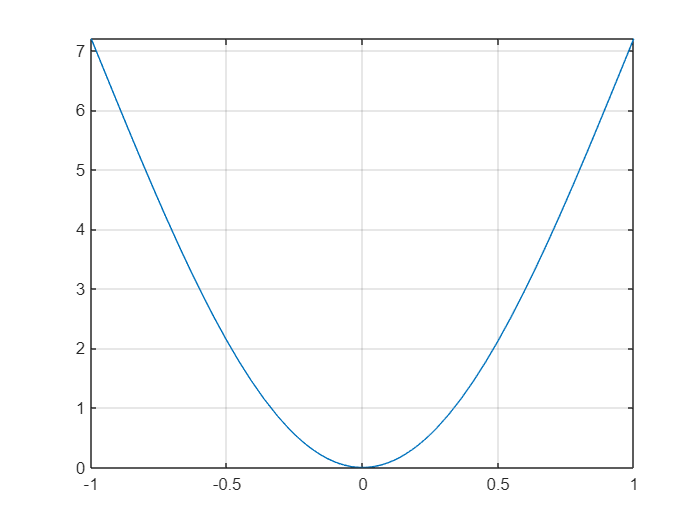

clear
syms f(x)

f(x) = x^2 + 4 * x * sin(x) + (2 * sin(x))^2;

clf('reset')
fplot(f, [-1, 1])
yline(0)
grid on
df(x) = diff(f, x);
d2f(x) = diff(df, x);


f = matlabFunction(f);
df = matlabFunction(df);
d2f = matlabFunction(d2f);

help newton
[p, err, k, y] = newton(f, df, 1, 1e-15, 1e-15, 100)

Newton Acelerado: $x_n =x_{n-1} -M\frac{\;f\left(x_{n-1} \right)}{f^{\prime } \left(x_{n-1} \right)}$


$$f\left(x\right)={\left(x+2\sin \left(x\right)\right)}^2$$


mi(x) = df(x) / 2; % Cero acelerado

  Entrada - f funcion creada con @
          - df funcion derivada creada con @
          - p0 es la aproximacion inicial a cero de  f
 	      - delta es la tolerancia para  p0
 	      - epsilon es la tolerancia para los valores de la funcion  y
 	      - max1 es el numero maximo de iteraciones
  Salida  - p0 es la aproximacion de Newton-Raphson hacia cero
 	      - err es el error estimado para  p0
 	      - k es el numero de iteraciones
 	      - y es el valor de la funcion  f(p0)



mi = matlabFunction(mi);

relerr = 2.0000

p = 1.0191e-08

err = 1.0191e-08

k = 26

y = 9.3465e-16

[p, err, k, y] = newton(f, mi, 1, 1e-15, 1e-15, 100)

Newton Modificado: $\mu \left(x\right)=\frac{f\left(x\right)}{f^{\prime } \left(x\right)}$ : $x_n =x_{n-1} -\frac{\;\mu \left(x_{n-1} \right)}{\mu^{\prime } \left(x_{n-1} \right)}$

[p, err, k, y] = newtonMod(f, df, d2f, 1, 1e-15, 1e-15, 100)

**4. **Para los siguientes problemas de la forma $f\left(x\right)=0$, aproxime una raíz por medio del método de Newton.

**(a)** $\frac{1}{x}-2^x =0$ en $\left\lbrack \ldotp 2,1\right\rbrack$

**(b)** $2^{-x} +e^x +2\;\cos \left(x\right)-6=0$, en $\left\lbrack 1,3\right\rbrack$

**(c)** $x-\tan \left(x\right)=0$ en $\left\lbrack -1\ldotp 5,1\right\rbrack$ . *¿Qué dificultades encuentra? ¿Cree que este problema lo puede resolver en un intervalo arbitrario?*

**(d)** $\frac{1}{x}-\tan \left(x\right)=0$, en $\left(\ldotp 5,1\right)$ *¿Qué dificultades encuentra? ¿Cree que este problema lo puede resolver en un intervalo arbitrario?*

**13. **En cada una de las siguientes ecuaciones, determine un intervalo $\left\lbrack a,b\right\rbrack$ en el que converge la iteración de **punto fijo**. Estime la cantidad de iteraciones necesarias para obtener aproximaciones del punto fijo con una exactitud de `1e-5` . Utilice el punto medio del intervalo seleccionado como primera aproximación $p_0$:

**(a) **$\frac{\cos \left(x\right)+\sin \left(x\right)}{2}$        **(b)** $\frac{5}{x^2 }+2$

relerr = 7.3919e+07

p = 1.3235e-23

err = 3.6960e-08

k = 4

y = 1.5765e-45

**2. **Utilice el método de Newton para aproximar el valor de $x$ que produce el valor de $y=1\;/\;x$ más cercano al punto $\left(2,1\right)$.

p = 4.1746e-17

err = 4.5456e-06

k = 4

y = 1.5685e-32